# 2D primary mixed-mode SSM for the dynamic buckling of a beam

In this example, we apply a sufficiently large axial compression force to a pinned-pinned von Kármán beam [1] and seek to derive an SSM-reduced nonlinear model for the ensuing buckling dynamics [2].

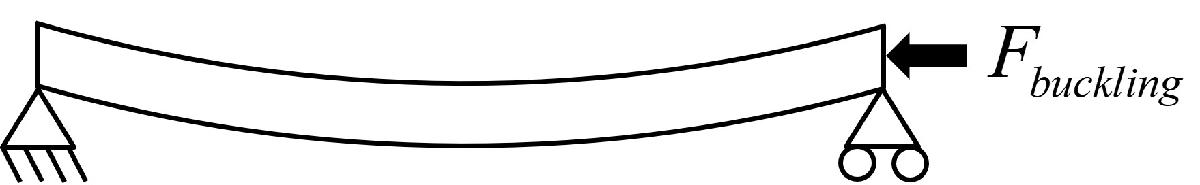

[1] S. Jain, P. Tiso, and G. Haller, Exact nonlinear model reduction for a von Kármán beam: slow-fast decomposition and spectral submanifolds, *Journal of Sound and Vibration* 423 (2018) 195-211. [https://doi.org/10.1016/j.jsv.2018.01.049](https://doi.org/10.1016/j.jsv.2018.01.049)

[2] G. Haller, B. Kaszás, A. Liu and J.Axås, Data-Driven Nonlinear Model Reduction to Fractional and Mixed-Mode Spectral Submanifolds, to be submitted.

clearvars
close all
addpath tools

## Example setup

The $N$-degree of freedom dynamical system is of the form


$$\mathbf{M\ddot{q}} + \mathbf{C\dot{q}} + \mathbf{Kq} + \mathbf{f}(\mathbf{q},\mathbf{\dot{q}}) 
= \mathbf{0}$$


where $\mathbf{f}=\mathcal{O}(|\mathbf{q}|^2,|\mathbf{\dot{q}}|^2,|\mathbf{q}||\mathbf{\dot{q}}|)$ represents the nonlinearities and $\mathbf{M}$, $\mathbf{C}$, and $\mathbf{K}$ are the $n\times n$ mass, stiffness, and damping matrices, respectively.

We rewrite the system in first-order form as


$$\mathbf{\dot{x}} = \mathbf{A}\mathbf{x} + \mathbf{G}(\mathbf{x}) = \mathbf{F}(\mathbf{x})$$


with

$\mathbf{x}=\left[\begin{array}{c}\mathbf{q}\\\dot{\mathbf{q}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}\mathbf{0}  & \mathbf{I}\\-\mathbf{M}^{-1}\mathbf{K} & -\mathbf{M}^{-1}\mathbf{C} \end{array}\right],\quad\mathbf{G}(\mathbf{x})=\left[\begin{array}{c}  \mathbf{0} \\ -\mathbf{M}^{-1}\mathbf{f}(\mathbf{x})\end{array}\right]$.

Building FE model
Assembling M,C,K matrices
Applying boundary conditions
Solving undamped eigenvalue problem


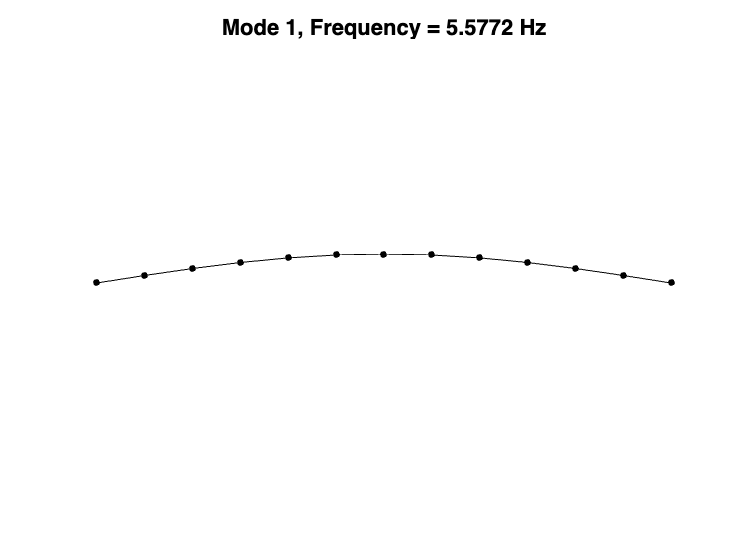

Assembling external force vector
Getting nonlinearity coefficients
Assembling Tensors
Total time spent on model assembly = 00:00:00


nElements = 12;
l = 2; h = 1e-2; b = 5e-2; % Mesh parameters
E = 190e9;  % Young's modulus
[M, C, K, fnl, fExt, obsdof, PlotFieldonDefMesh] = buildModelBuckling(nElements,l,h,b,E);

n = size(M,1);    % mechanical dofs (axial def, transverse def, angle)

We apply buckling force larger than the Euler's critical load


$$F = \frac{N^2 \pi ^2 EI}{L^2} = \frac{\pi ^2 Ebh^3}{12 L^2}$$


loads = [1.1]*pi^2* E * b*(h)^3 /12 / l^2;  
loadvector = loads.*fExt;
[F_0, ~] = functionFromTensors(M, C, K, fnl);
unstable_fp = getStaticResponseIC(K, M, F_0, -loadvector, 0, PlotFieldonDefMesh); 

## Training data generation

We divide the data into a training set containing four trajectories, and a test set containing two trajectories for validation. 

nTraj = 6; % numbers of training trajectories
indTest = 5:6;
indTrain = 1:4;

Since in SSMLearn, the SSM is attached to the fixed point at the origin, we move the origin to the unstable steady state under the buckling force, and compute the corresponding eigenvalues. To save execution time and avoid rerunning the system differentiation, `newSystem` can be set to `false`.

newSystem = false;
if newSystem
    [~, lambda, ~] = functionFromTensorsFP(M, C, K, fnl, loadvector, unstable_fp);
else
    load vonkarmandata/A_t.mat
    [~, lambda, ~] = functionFromTensorsFP(M, C, K, fnl, loadvector, unstable_fp, A_t);
end
lambda_10 = sort(lambda); 
disp('first 10 eigenvalues of the system:'); disp( lambda_10(1:10) );

first 10 eigenvalues of the system:
   1.0e+02 *

   0.1106 + 0.0000i
  -0.1110 + 0.0000i
  -0.0036 - 1.1936i
  -0.0036 + 1.1936i
  -0.0183 - 2.9556i
  -0.0183 + 2.9556i
  -0.0580 - 5.4150i
  -0.0580 + 5.4150i
  -0.1419 - 8.5819i
  -0.1419 + 8.5819i



[F, ~] = functionFromTensors(M, C, K, fnl, loadvector, 0);

We then apply static force to get initial conditions. The initial conditions of the training trajectories can either be generated by applying a small perturbation to the unstable fixed point, or by applying a large transverse force at middle node. For testing data, symmetric forces with different ampitudes are applied. 

loadvector_IC = zeros(size(loadvector));
loadvector_IC(18) = 1; % transverse direction of midpoint, dof 18
loadAmp = [1e-4 -1e-4 1e4 -1e4 6e3 -6e3]; % amplitude of static forces

IC = zeros(2*n,nTraj);
for i = 1 : nTraj % calculate initial conditions
    IC(:,i) = getStaticResponseIC(K, M, F_0, loadvector_IC*loadAmp(i), 0, PlotFieldonDefMesh);
end    

Then the trajectories are integrated. Simulation time is about 5 mins each trajectory. To save execution time and avoid rerunning the simulation, `newMeasurement` can be set to `false`. 

newMeasurement = false;
observable = @(x) x; % observe full system
slowTimeScale = 2*pi/abs(lambda(1));
if newMeasurement
    numberPeriods = 150;
    numberPointsPerPeriod = 100; 
    endTime = numberPeriods*slowTimeScale;
    nSamp = numberPeriods*numberPointsPerPeriod+1;
    dt = endTime/(nSamp-1);
    xData = integrateTrajectories(F, endTime, IC , nSamp, observable, 'odesolver', @ode45);
    DataInfo = struct('nElements', nElements, 'loadvector', loadvector);
    save('vonkarmandata/dataVKDecay.mat', 'DataInfo', 'xData', 'dt', 'endTime', 'nSamp', 'lambda')
else
    load vonkarmandata/dataVKDecay.mat
    if nElements ~= DataInfo.nElements
       error('The loaded data comes from a model with a different number of elements.')
    end
end

## Data analysis

We need to make sure that the data that we use to identify the mixed-mode SSM lies close to it. We keep only the time interval `sliceInt`.

sliceInt = [5*slowTimeScale, endTime]; xDataTrunc(1:2,:) = sliceTrajectories(xData(1:2,:), sliceInt);
sliceInt = [10*slowTimeScale, endTime]; xDataTrunc(3:6,:) = sliceTrajectories(xData(3:6,:), sliceInt);

We observe three DoFs: transverse displacement and velocity of midpoint, and axial displacement of right endpoint. 

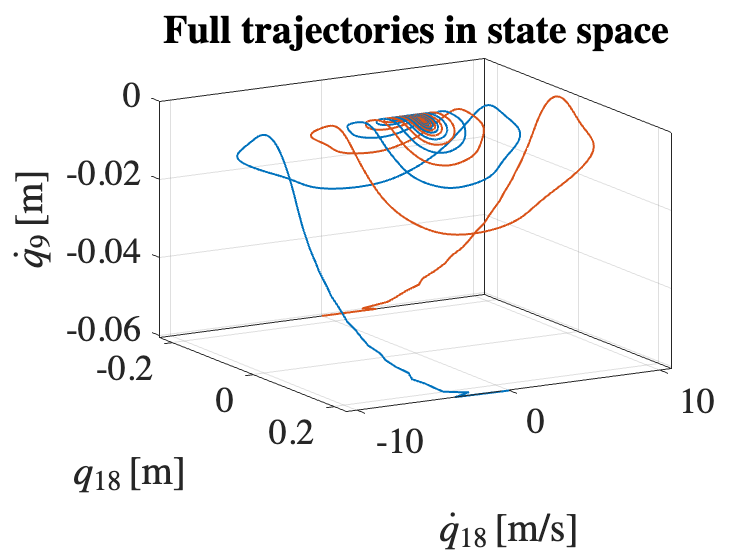

customFigure(); 
for iTraj = 3:4
    plot3(xData{iTraj,2}(18,:), xData{iTraj,2}(54,:), xData{iTraj,2}(35,:),'Linewidth',1,'Displayname',['Trajectory ' num2str(iTraj)])
end
xlabel('$q_{18} \, [$m$]$','Interpreter','latex'); 
ylabel('$\dot{q}_{18} \, [$m/s$]$','Interpreter','latex'); 
zlabel(['$\dot{q}_{9} \, [$m$]$'],'Interpreter','latex'); 
title('Full trajectories in state space')
view(60,20)

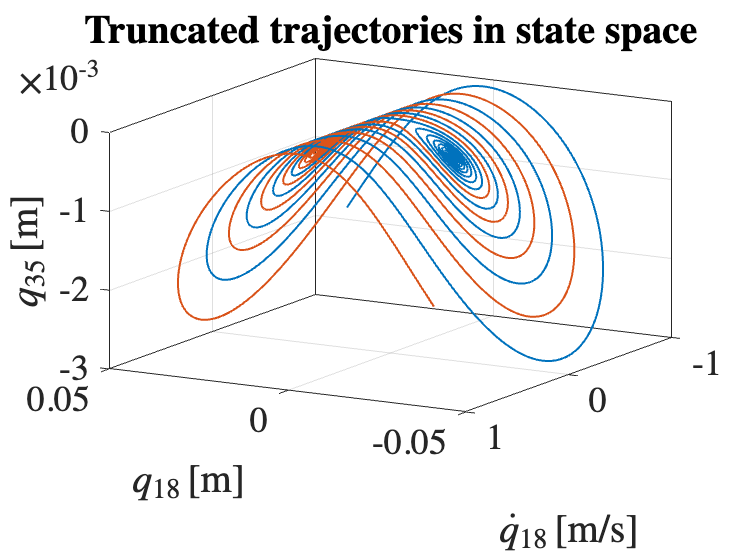


customFigure(); 
for iTraj = 3:4
    plot3(xDataTrunc{iTraj,2}(18,:), xDataTrunc{iTraj,2}(54,:), xDataTrunc{iTraj,2}(35,:),'Linewidth',1,'Displayname',['Trajectory ' num2str(iTraj)])
end
xlabel('$q_{18} \, [$m$]$','Interpreter','latex'); 
ylabel('$\dot{q}_{18} \, [$m/s$]$','Interpreter','latex'); 
zlabel(['$q_{35} \, [$m$]$'],'Interpreter','latex'); 
title('Truncated trajectories in state space')
view(-150,20)

## Datadriven manifold fitting

The measured trajectories are assumed to lie close to a two-dimensional manifold that is tangent at the origin to the eigenspace corresponding to the first pair of real eigenvalues, and containing the two stable fixed points.

We seek the $2n\times m_M$ polynomial coefficient matrix $H$ of the manifold on the form

$y = V_e V_e^\top y + H \phi_{m,2:M}(V_e^\top y)$,

where the function $\phi_{m,2:M}(q)$ computes a vector of all $m_M$ monomials from orders 2 up to $M$ of an $m$-vector $q$. This optimization problem is formulated as the minimization of a cost function computed from the measured data $y_k$,


$$C_r(V_e,H) = \sum_{k=1}^N ||y_k - V_eV_e^\top y_k - H\phi_{m,2:M}(V_e^\top 
y_k) ||$$


to find $H$ and the $2n\times 2$ eigenspace matrix $V_e$, under the constraints that $V_e^\top H=0$ and $V_e^\top V_e = I$. The minimization is performed with the Matlab function `fmincon` in `IMGeometry`.

SSMDim = 2;  SSMOrder = 7; 
[IMInfo, SSMChart, SSMFunction] = IMGeometry(xDataTrunc(indTrain,:), SSMDim, SSMOrder);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    3.059760e-07    5.245e-14    3.037e-07

Initial point is a local minimum that satisfies the constraints.

Optimization completed because at the initial point, the objective function is non-decreasing 
in feasible directions to within the value of the optimality tolerance, and 
constraints are satisfied to within the value of the constraint tolerance.

<

Now that we have computed the eigenspace of the manifold, we pass to the reduced coordinates $y$ by projecting all trajectories onto the eigenspace $\eta = V_e^\top y$. We plot the trajectories in reduced coordinates:

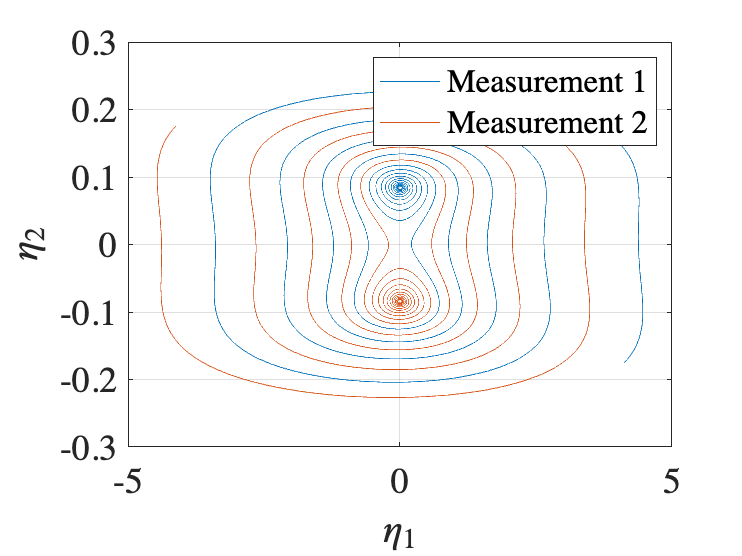

etaData = projectTrajectories(IMInfo, xData);
etaDataTrunc = projectTrajectories(IMInfo, xDataTrunc);
plotReducedCoordinates(etaDataTrunc(3:4,:));

We plot the trajectories and the 2D primary SSM in state space:

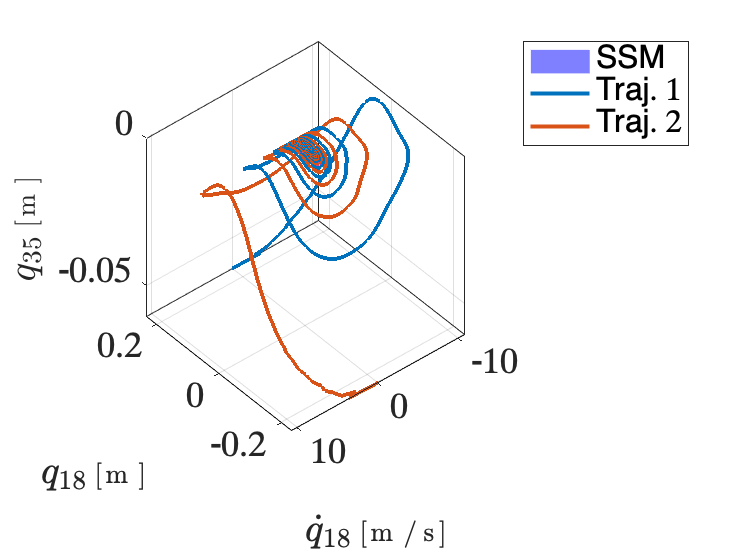

plotSSMandTrajectories(IMInfo, [18 54 35], xData(3:4,:), etaDataTrunc(3:4,:),'Margin',5)
xlabel('$q_{18} \, [$m$]$','Interpreter','latex'); 
ylabel('$\dot{q}_{18} \, [$m/s$]$','Interpreter','latex'); 
zlabel(['$q_{35} \, [$m$]$'],'Interpreter','latex'); 
view(-130,40);

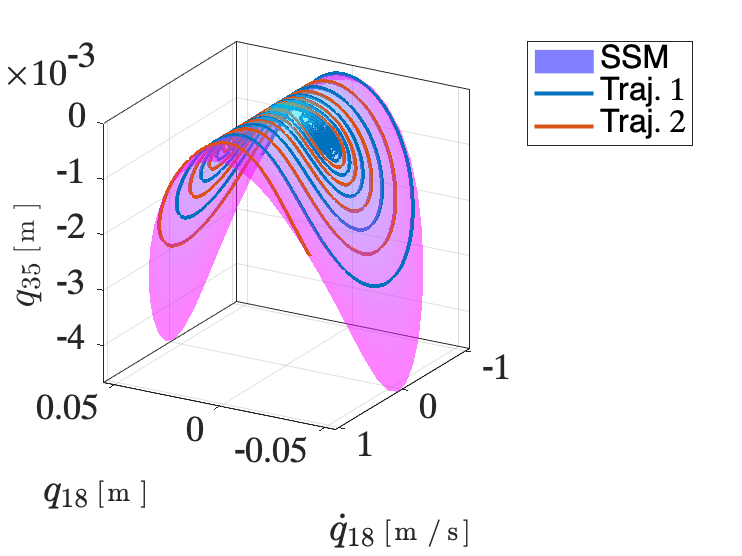


plotSSMandTrajectories(IMInfo, [18 54 35], xDataTrunc(3:4,:), etaDataTrunc(3:4,:))
xlabel('$q_{18} \, [$m$]$','Interpreter','latex'); 
ylabel('$\dot{q}_{18} \, [$m/s$]$','Interpreter','latex'); 
zlabel(['$q_{35} \, [$m$]$'],'Interpreter','latex'); 
view(-150,20);

We compute the manifold fitting error:

xxDataTrunc = transformTrajectories(IMInfo.parametrization.map, etaDataTrunc);
normedTrajDist = computeTrajectoryErrors(xxDataTrunc, xDataTrunc);
Error = mean(normedTrajDist(indTest));
disp('Manifold fitting error:'); disp( Error );

Manifold fitting error:
   9.6537e-04



## Reduced order model

We compute a model for the reduced dynamics with the truncated training data projected onto the manifold. The function `IMDynamicsFlow` fits a polynomial map


$$\dot{\eta} = R(\eta) = W_r \phi(\eta)$$


where $\phi(\eta)$ again computes a vector of all monomials of $\eta$, and  $W_r$ is a matrix of polynomial coefficients. 

ROMOrder = 7; 
RDInfo = IMDynamicsFlow(etaDataTrunc(indTrain,:),'R_PolyOrd', ROMOrder, 'style', 'modal');

Estimation of the reduced dynamics...  Done. 


We transform the truncated initial condition of our test trajectory according to the obtained change of coordinates, and integrate our reduced order evolution rule to predict the development of the trajectory.

[xRec, etaRec, zRec] = advect(IMInfo, RDInfo, xDataTrunc);

## Evaluation of reduced dynamics

Compare the real eigenvalue of the system and data-driven fit from SSMLearn:

lambda = sort(lambda);
DSEigenvalues = lambda(1:SSMDim)

DSEigenvalues =    10.9910
  -11.0363


reconstructedEigenvalues = sort(RDInfo.eigenvaluesLinPartFlow)

reconstructedEigenvalues =   -11.0636
   11.0132


The normalized mean trajectory error NMTE is computed as the average distance of the predicted trajectory to the measured one in the observable space, normalized by the observable vector with maximum norm in the data. 

normedTrajDist = computeTrajectoryErrors(xRec, xDataTrunc);
NMTE = mean(normedTrajDist(indTest));
disp('normalized mean trajectory error NMTE:'); disp( Error );

normalized mean trajectory error NMTE:
   9.6537e-04



We compare the testing data and their predictions in reduced coordinates:

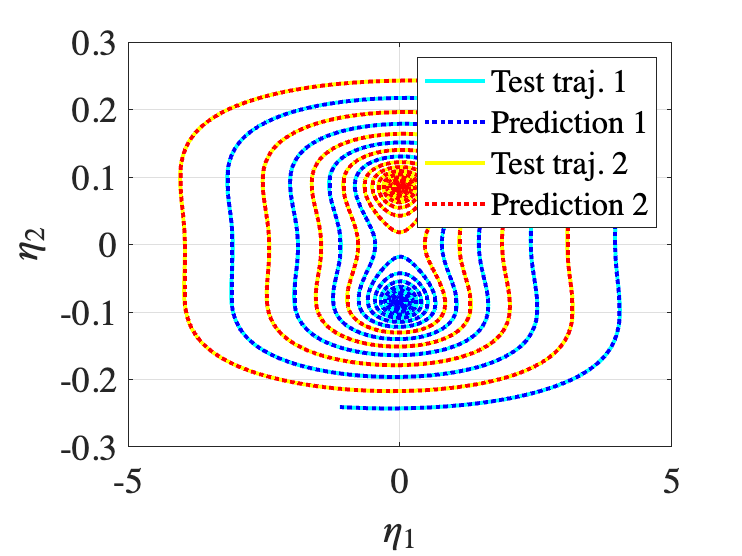

customFigure(); legend();
plot(etaDataTrunc{indTest(1),2}(1,:), etaDataTrunc{indTest(1),2}(2,:), 'c','LineWidth', 2,'DisplayName', 'Test traj. 1')
plot(etaRec{indTest(1),2}(1,:), etaRec{indTest(1),2}(2,:), ':b', 'LineWidth', 2, 'DisplayName', 'Prediction 1')
plot(etaDataTrunc{indTest(2),2}(1,:), etaDataTrunc{indTest(2),2}(2,:),'y', 'LineWidth', 2,'DisplayName', 'Test traj. 2')
plot(etaRec{indTest(2),2}(1,:), etaRec{indTest(2),2}(2,:), ':r', 'LineWidth', 2, 'DisplayName', 'Prediction 2')
xlabel('$\eta_1$', 'Interpreter', 'latex')
ylabel('$\eta_2$', 'Interpreter', 'latex')

We plot the testing data and their predictions in model coordinates by a linear transformation:

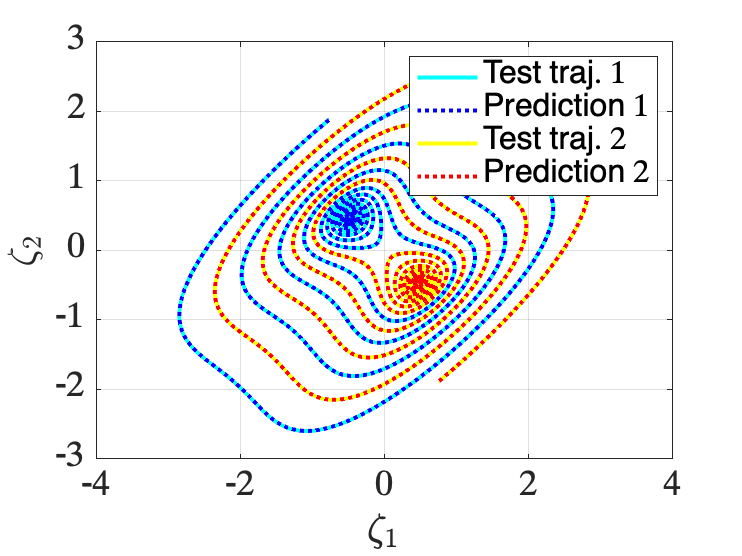

zData = transformTrajectories(RDInfo.inverseTransformation.map,etaDataTrunc);
customFigure(); legend();
plot(zData{indTest(1),2}(1,:), zData{indTest(1),2}(2,:), 'c','LineWidth', 2, 'DisplayName', 'Test traj. 1')
plot(zRec{indTest(1),2}(1,:), zRec{indTest(1),2}(2,:), ':b', 'LineWidth', 2, 'DisplayName', 'Prediction 1')
plot(zData{indTest(2),2}(1,:), zData{indTest(2),2}(2,:),'y', 'LineWidth', 2, 'DisplayName', 'Test traj. 2')
plot(zRec{indTest(2),2}(1,:), zRec{indTest(2),2}(2,:), ':r', 'LineWidth', 2, 'DisplayName', 'Prediction 2')
xlabel('$\zeta_1$', 'Interpreter', 'latex')
ylabel('$\zeta_2$', 'Interpreter', 'latex')

We also compare the testing data and their predictions in full state space:

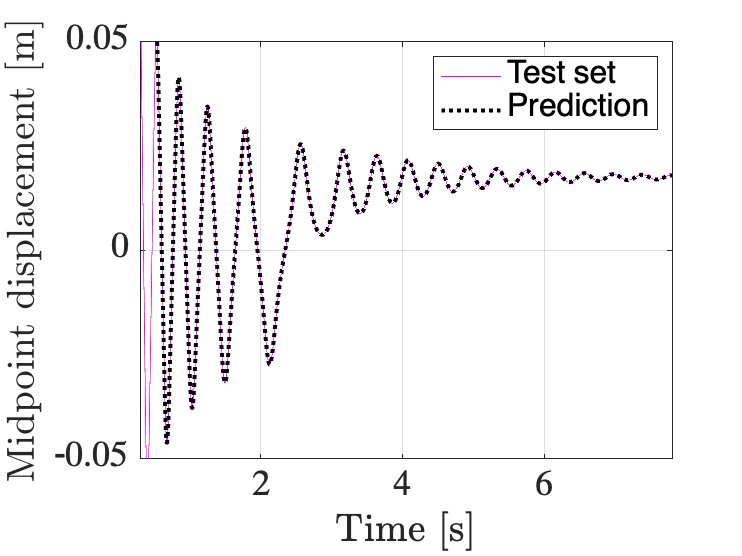

plotTrajectories(xData(indTest(1),:), xRec(indTest(1),:), 'm', fix(n/2), {'Test set', 'Prediction'})
ylabel('Midpoint displacement $[$m$]$','Interpreter','latex')
xlabel('Time $[$s$]$','Interpreter','latex')
xlim([0.3 7.8]); ylim([-0.05 0.05]);

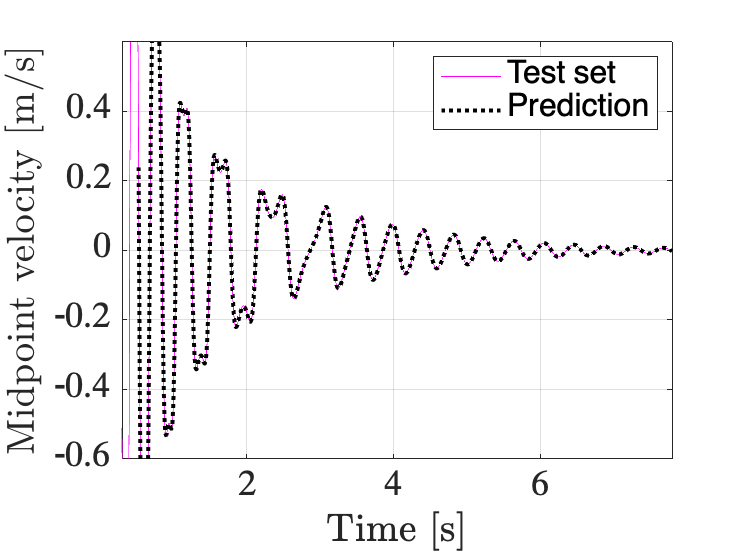


plotTrajectories(xData(indTest(1),:), xRec(indTest(1),:), 'm', 54, {'Test set', 'Prediction'})
ylabel('Midpoint velocity $[$m/s$]$','Interpreter','latex')
xlabel('Time $[$s$]$','Interpreter','latex')
xlim([0.3 7.8]); ylim([-0.6 0.6]);